
l1 = 0.4;
l2 = 0.3;
l3 = 0.2;
l4 = 0.1;

xO = 0.3;
yO = 0.45;

initial_theta = [pi/3; 0; 0; 0];


%IKP for the given trajectory
thetas = inverse_kinematics_with_obstacle_avoidance(trajectory, initial_theta, l1, l2, l3, l4, xO, yO);

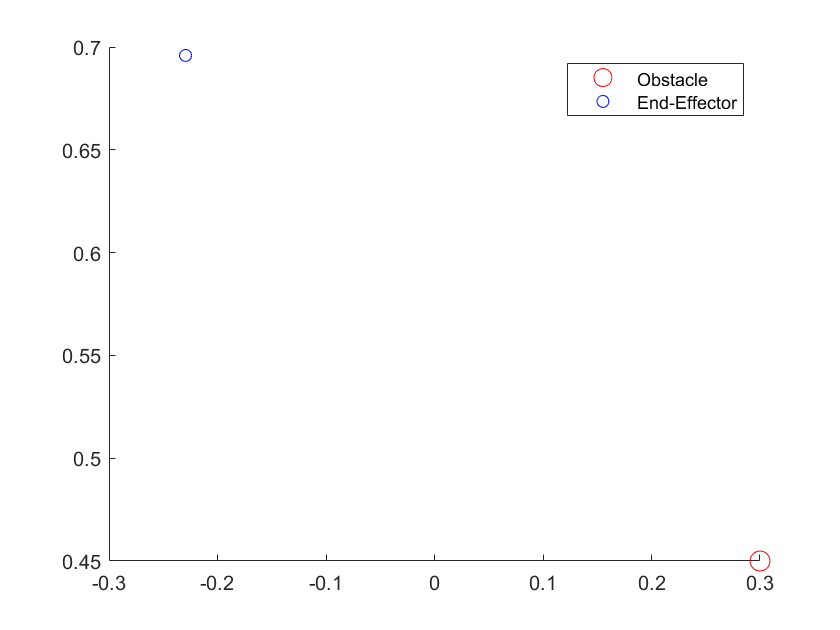



thetas = inverse_kinematics_with_obstacle_avoidance(trajectory, initial_theta, l1, l2, l3, l4, xO, yO);

figure;
hold on;
plot(xO, yO, 'ro', 'MarkerSize', 10, 'DisplayName', 'Obstacle');


end_effector_plot = plot(0, 0, 'bo', 'DisplayName', 'End-Effector');


for i = 1:size(thetas, 1)

    [x, y, ~] = forward_kinematics(thetas(i, 1), thetas(i, 2), thetas(i, 3), thetas(i, 4), l1, l2, l3, l4);
    

    set(end_effector_plot, 'XData', x, 'YData', y);
    

    drawnow;
end

legend;
hold off;


thetas = inverse_kinematics_with_obstacle_avoidance(trajectory, initial_theta, l1, l2, l3, l4, xO, yO);


figure;
hold on;
plot(xO, yO, 'ro', 'MarkerSize', 10, 'DisplayName', 'Obstacle');


for i = 1:size(thetas, 1)
    [x, y, ~] = forward_kinematics(thetas(i, 1), thetas(i, 2), thetas(i, 3), thetas(i, 4), l1, l2, l3, l4);
    

    plot(x, y, 'bo', 'DisplayName', 'End-Effector');
    

    drawnow;
end

legend;

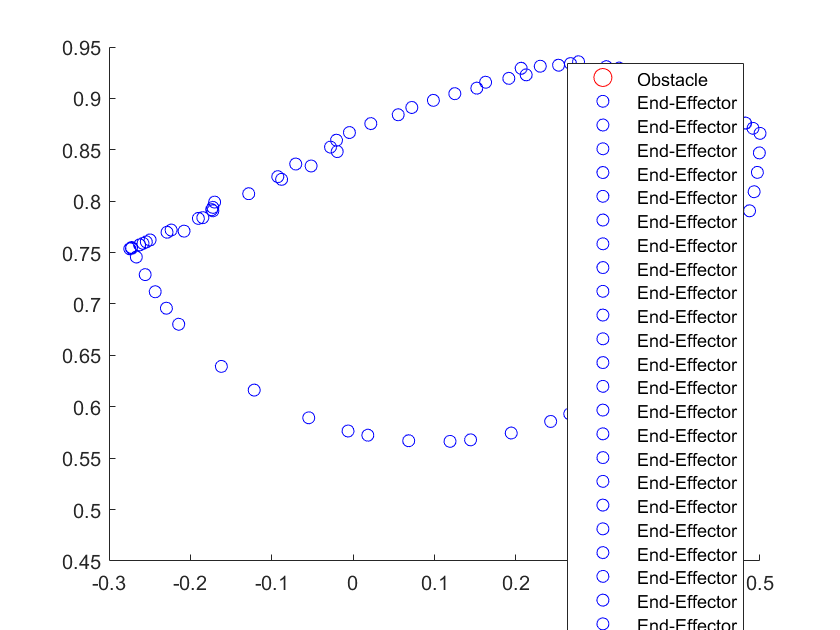

hold off;

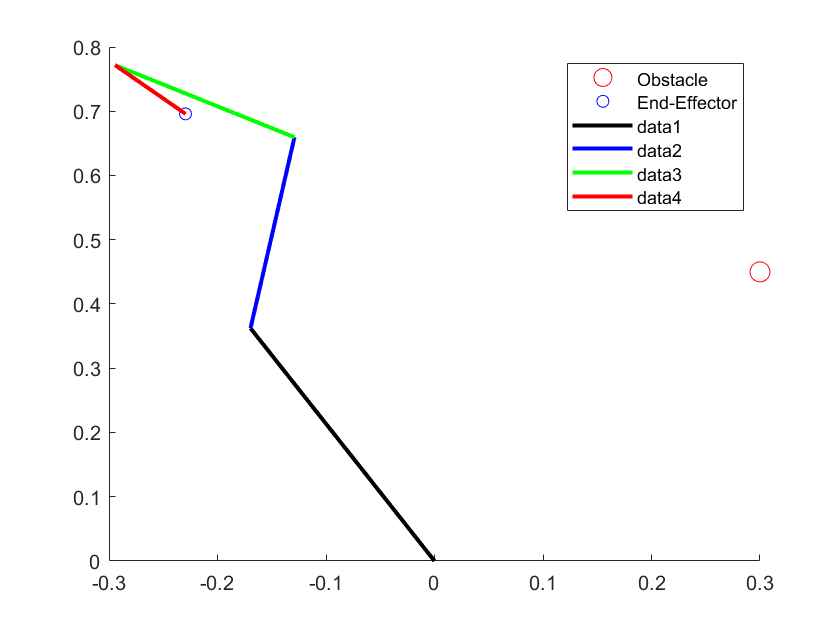


thetas = inverse_kinematics_with_obstacle_avoidance(trajectory, initial_theta, l1, l2, l3, l4, xO, yO);


figure;
hold on;
plot(xO, yO, 'ro', 'MarkerSize', 10, 'DisplayName', 'Obstacle');
end_effector_plot = plot(0, 0, 'bo', 'DisplayName', 'End-Effector');

link1 = line([0 0], [0 0], 'LineWidth', 2, 'Color', 'k');
link2 = line([0 0], [0 0], 'LineWidth', 2, 'Color', 'b');
link3 = line([0 0], [0 0], 'LineWidth', 2, 'Color', 'g');
link4 = line([0 0], [0 0], 'LineWidth', 2, 'Color', 'r');


for i = 1:size(thetas, 1)

    [x1, y1, phi1] = forward_kinematics(thetas(i, 1), 0, 0, 0, l1, 0, 0, 0);
    [x2, y2, phi2] = forward_kinematics(thetas(i, 1), thetas(i, 2), 0, 0, l1, l2, 0, 0);
    [x3, y3, phi3] = forward_kinematics(thetas(i, 1), thetas(i, 2), thetas(i, 3), 0, l1, l2, l3, 0);
    [x4, y4, phi4] = forward_kinematics(thetas(i, 1), thetas(i, 2), thetas(i, 3), thetas(i, 4), l1, l2, l3, l4);

    set(link1, 'XData', [0, x1], 'YData', [0, y1]);
    set(link2, 'XData', [x1, x2], 'YData', [y1, y2]);
    set(link3, 'XData', [x2, x3], 'YData', [y2, y3]);
    set(link4, 'XData', [x3, x4], 'YData', [y3, y4]);


    set(end_effector_plot, 'XData', x4, 'YData', y4);
    

    drawnow;
end

legend;
hold off;

## **IKP**

function thetas = inverse_kinematics_with_obstacle_avoidance(trajectory, initial_theta, l1, l2, l3, l4, xO, yO)
    num_points = size(trajectory, 1);
    thetas = zeros(num_points, 4);
    

    theta = initial_theta;
    
    for i = 1:num_points
        target = trajectory(i, :);
        

        options = optimoptions('fmincon', 'Algorithm', 'sqp', 'Display', 'off');
        
        % Objective function: minimize joint velocities and avoid obstacle
        objective = @(theta) norm(theta - thetas(max(i-1, 1), :))^2 + ...
            1e3 / (norm(forward_kinematics(theta(1), theta(2), theta(3), theta(4), l1, l2, l3, l4) - [xO, yO, 0]) + 1e-6);
        
        % Constraint function: end-effector must reach target position
        constraint = @(theta) forward_kinematics_constraint(theta, target, l1, l2, l3, l4);
        
        % Solve the optimization problem
        theta = fmincon(objective, theta, [], [], [], [], [], [], constraint, options);
        
        thetas(i, :) = theta;
    end
end

function [c, ceq] = forward_kinematics_constraint(theta, target, l1, l2, l3, l4)
    [x, y, phi] = forward_kinematics(theta(1), theta(2), theta(3), theta(4), l1, l2, l3, l4);
    ceq = [x - target(1), y - target(2), phi - target(3)];
    c = [];
end

%FKP
function [x, y, phi] = forward_kinematics(theta1, theta2, theta3, theta4, l1, l2, l3, l4)

    x = l1*cos(theta1) + l2*cos(theta1 + theta2) + l3*cos(theta1 + theta2 + theta3) + l4*cos(theta1 + theta2 + theta3 + theta4);
    y = l1*sin(theta1) + l2*sin(theta1 + theta2) + l3*sin(theta1 + theta2 + theta3) + l4*sin(theta1 + theta2 + theta3 + theta4);
    phi = theta1 + theta2 + theta3 + theta4;
end

%Jacobian for RRRR
function J = jacobian_matrix(theta1, theta2, theta3, theta4, l1, l2, l3, l4)
    
    J = zeros(3, 4);
    

    J(1, 1) = -l1*sin(theta1) - l2*sin(theta1 + theta2) - l3*sin(theta1 + theta2 + theta3) - l4*sin(theta1 + theta2 + theta3 + theta4);
    J(1, 2) = -l2*sin(theta1 + theta2) - l3*sin(theta1 + theta2 + theta3) - l4*sin(theta1 + theta2 + theta3 + theta4);
    J(1, 3) = -l3*sin(theta1 + theta2 + theta3) - l4*sin(theta1 + theta2 + theta3 + theta4);
    J(1, 4) = -l4*sin(theta1 + theta2 + theta3 + theta4);
    

    J(2, 1) = l1*cos(theta1) + l2*cos(theta1 + theta2) + l3*cos(theta1 + theta2 + theta3) + l4*cos(theta1 + theta2 + theta3 + theta4);
    J(2, 2) = l2*cos(theta1 + theta2) + l3*cos(theta1 + theta2 + theta3) + l4*cos(theta1 + theta2 + theta3 + theta4);
    J(2, 3) = l3*cos(theta1 + theta2 + theta3) + l4*cos(theta1 + theta2 + theta3 + theta4);
    J(2, 4) = l4*cos(theta1 + theta2 + theta3 + theta4);

    J(3, :) = [1, 1, 1, 1];
end
